# Optimización unidimensional usando aproximación de tipo interpolación cuadrática en MATLAB

**Alumno:** Pablo Ruiz Molina

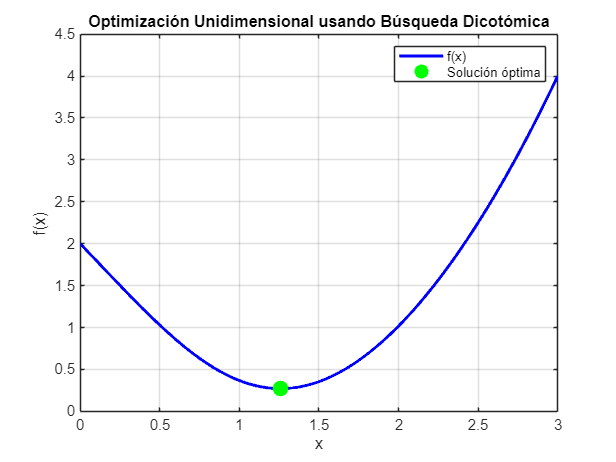

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x-1).^2 + exp(-x.^2);  % Función unimodal

% Definir los límites del intervalo de búsqueda
a = 0;
b = 3;

% Parámetros de la búsqueda dicotómica
delta = 1e-6;  % Tolerancia (delta)

% Inicialización de las variables
max_iter = 100;  % Número máximo de iteraciones

% Obtener la solución óptima final
[f_opt, x_opt, iter] = incu(f, a, (a + b)/2, b, delta, max_iter);

% Graficar la función objetivo
x_vals = linspace(a, b, 1000);
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
legend('f(x)');
hold on;
% Marcar la solución óptima en el gráfico
plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando Búsqueda Dicotómica');
grid on;
hold off;

% Mostrar los resultados
disp('Punto óptimo (x):');

Punto óptimo (x):


disp(x_opt);

    1.2583



disp('Valor óptimo de f(x):');

Valor óptimo de f(x):


disp(f_opt);

    0.2720



## Anexo

function [f_opt, x_opt, iter] = incu(f, x1, x2, x3, delta, max_iter)
    % Método de interpolación cuadrática
    % Entradas:
    %   f: función objetivo
    %   x1, x2, x3: puntos iniciales en los que x2 < x1 y x2 < x3
    %   delta: tolerancia para la convergencia
    %   max_iter: número máximo de iteraciones
    %
    % Salidas:
    %   f_opt: valor de la función dónde se alcanza el óptimo 
    %   x_opt: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Inicialización iteraciones
    iter = 0; 
    
    % Paso 1: mientras (b - a) >= tol y no max_iter
    while iter < max_iter 
        iter = iter + 1;

        % Paso 2:evaluar la función en los 3 puntos
        f1 = f(x1); f2 = f(x2); f3 = f(x3);

        % Paso 3: calcular el valor mínimo del polinomio interpolador
        num = ((x2^2-x3^2)*f1 + (x3^2-x1^2)*f2 + (x1^2-x2^2)*f3);
        den = 2*((x3-x2)*f1 + (x1-x3)*f2 + (x2-x1)*f3);
        x = -num/den;
        
        % Paso 4: devolver mínimo si se cumple el criterio de parada
        if abs(x2 - x) < delta
            x_opt = x;
            f_opt = f(x_opt);
            return
        else
            % Paso 5: se reduce el intervalo
            if x2 <= x
                x1 = x2; x2 = x; 
            else
                x3 = x2; x2 = x;
            end
        end
    end
    % Paso 6: Si no converge, devolver x_opt = 0;
    x_opt = 0;
    f_opt = f(x_opt);
end